# Práctica 2 - Modelo Goodwin

Luis Alejandro Baena Marín - Juan Camilo Bermúdez Colorado

## 1. Introducción

En el estudio de la dinámica macroeconómica, la interacción entre el empleo, la participación salarial y el crecimiento económico ha sido un área clave de interés. Uno de los modelos más conocidos que trata de capturar estas relaciones es el modelo de crecimiento cíclico de Richard Goodwin, propuesto en 1967. Este modelo utiliza ecuaciones diferenciales no lineales para describir la interacción entre la participación salarial ($\omega$) y la tasa de empleo ($\lambda$) a lo largo del tiempo, dentro de una economía capitalista.

El modelo de Goodwin se basa en principios marxistas, donde los ciclos económicos son explicados como el resultado de la lucha de clases entre los trabajadores, que buscan maximizar los salarios, y los capitalistas, que buscan maximizar las ganancias. Las ecuaciones fundamentales del modelo representan la evolución de la participación salarial y la tasa de empleo en función de variables como la productividad, la depreciación del capital y el crecimiento poblacional.

### 1.1. Modelo de Goodwin

        
$$\left\{
\begin{array}{ll}
\dot{\omega} = \omega \left( \frac{\phi_1}{(1 - \lambda)^2} - \phi_0 - \alpha \right) \\
\dot{\lambda} = \lambda \left( \frac{1 - \omega}{\nu} - \alpha - \beta - \delta \right)
\end{array}
\right. \\$$


donde:

        
$$\omega:  \text{participación salarial} \\
\lambda: \text{tasa de empleo} \\

\textbf{Definiciones de Parámetros:} \\
\bullet \ \nu : \text{Tasa de capital a salida.} \\
\bullet \ \alpha : \text{Tasa de crecimiento de productividad.} \\
\bullet \ \beta : \text{Tasa de crecimiento de población.} \\
\bullet \ \delta : \text{Tasa de depreciación.} \\
\bullet \ \phi_0 \text{ y } \phi_1 : \text{Parámetros de la curva de Phillips.} \\
\bullet \ t : \text{es el tiempo de simulación.}
$$


El objetivo de esta práctica es analizar el modelo de crecimiento económico de Goodwin como un sistema dinámico no lineal. Se realizará un análisis detallado del comportamiento del sistema utilizando la herramienta Global sensitivity and uncertainty analysis (GSUA), Simulink y MATLAB, con énfasis en los siguientes aspectos:

- **Curva de linealidad y punto de equilibrio**: Realizar una simulación para obtener la curva de linealidad y seleccionar el punto de equilibrio. Se calcularán el punto de equilibrio y la linealización, tanto analíticamente como con la función `linmod` de MATLAB.

- **Método de Routh-Hurwitz**: Aplicar este método al modelo lineal obtenido, para determinar el rango de estabilidad del sistema y darle valores a todos los parámetros menos a uno, para obtener el rango en el cuál el parámetro conserva la estabilidad del sistema.

- **Análisis de sensibilidad e incertidumbre**: Utilizar la herramienta GSUA para estudiar la influencia de las variaciones de parámetros en la respuesta temporal del sistema, y clasificar los parámetros del modelo según su sensibilidad.

La práctica permitirá una mejor comprensión de la dinámica cíclica del modelo de Goodwin y su relación con las políticas económicas que afectan el empleo y los salarios, centrándose en el análisis de las variables de salida $\omega$ (participación salarial) y $\lambda$ (tasa de empleo).

Para entender mejor el comportamiento del modelo, es importante tener en cuenta el significado intuitivo de los parámetros utilizados:

- $\nu$**: Tasa de capital a salida: **Este parámetro representa la proporción de la producción que se destina al capital. Un valor más alto indica que se requiere una mayor inversión de capital para generar una unidad de salida económica. En términos simples, refleja cuán intensiva en capital es la economía.

- $\alpha$**: Tasa de crecimiento de productividad: **Este parámetro mide cómo la productividad, es decir, la cantidad de output por unidad de trabajo, crece a lo largo del tiempo. Un aumento en la productividad puede traducirse en un mayor output económico sin necesidad de aumentar el empleo. Intuitivamente, es una medida de progreso técnico y eficiencia en la producción.

- $\beta$**: Tasa de crecimiento de población: **Este parámetro describe la velocidad a la que crece la población trabajadora. A mayor tasa de crecimiento de la población, más rápido aumentará la oferta de trabajadores en la economía, lo que puede ejercer presión sobre los salarios y el empleo.

- $\delta$**: Tasa de depreciación: **La tasa de depreciación indica la disminución en el valor del capital con el tiempo, debido al desgaste o la obsolescencia. Un valor alto sugiere que el capital en la economía se deteriora rápidamente, lo que podría requerir una mayor inversión continua para mantener el mismo nivel de producción.

- $\phi_0 \;y\;\phi_1$**: Parámetros de la curva de Phillips: **Estos parámetros representan la relación entre la inflación salarial y el desempleo, conocida como la curva de Phillips. El parámetro $\phi_0$ captura el nivel base de presión salarial que existe en la economía, mientras que $\phi_1$ mide cómo la tasa de empleo afecta la presión sobre los salarios. En el modelo de Goodwin, estas variables influyen directamente en la evolución de la participación salarial en función de la tasa de empleo.

En el modelo de Goodwin, se hacen dos suposiciones clave. La primera es que los salarios reales cambian en función de la tasa de empleo. A medida que aumenta el empleo, los salarios también suben debido a la mayor demanda de mano de obra, lo que refleja la idea de la curva de Phillips, donde hay una relación entre desempleo y crecimiento salarial. La segunda suposición es la ley de Say, que sostiene que todos los salarios se consumen y todas las ganancias se reinvierten en capital. Esto implica que el capital en la economía crece según las ganancias que quedan después de pagar los salarios y restando la depreciación.

### 1.2. Ecuación de estado

El modelo de Goodwin se puede representar mediante un sistema de ecuaciones diferenciales que describen la dinámica de la participación salarial $\omega$ y la tasa de empleo $\lambda$. En el contexto de este modelo, las variables $\omega$ y $\lambda$ se han renombrado como $x_1$ y $x_2$, respectivamente, para simplificar la notación. Las ecuaciones de estado son las siguientes:


$$\left\{
\begin{array}{ll}
\dot{x}_1 = x_1 \left( \frac{\phi_1}{(1 - x_2)^2} - \phi_0 - \alpha \right) \\ 
\dot{x}_2 = x_2 \left( \frac{1 - x_1}{\nu} - \alpha - \beta - \delta \right) + u_{input}
\end{array}
\right. $$


**Entrada externa o estímulo**: Se ha añadido un término $u_{\textrm{input}} \left(t\right)$, que representa cualquier intervención externa que influye directamente en la tasa de empleo $\lambda$. Este estímulo puede interpretarse como una política económica (como una política fiscal expansiva, subsidios, o cambios en las condiciones del mercado laboral) que afecta el nivel de empleo. Al incorporarla, el modelo permite simular cómo reacciona la economía ante perturbaciones externas o estímulos que no se encuentran dentro de la dinámica interna natural del sistema. Esto mejora la representatividad del modelo, al reflejar cómo las economías reales a menudo están influenciadas por intervenciones externas.

Esta entrada se integra en la ecuación de la tasa de empleo $x_{2\;}$($\lambda$), donde su derivada temporal describe el cambio en la tasa de empleo respecto al tiempo. La tasa de empleo se define como una proporción y, por tanto, es adimensional. Sin embargo, al considerar su derivada con respecto al tiempo, se obtiene una tasa de cambio, la cual tiene dimensiones de ${\left\lbrack T\right\rbrack }^{-1}$, es decir, unidades inversas de tiempo. Por lo tanto, para que $u_{\textrm{input}} \left(t\right)$ se integre correctamente en la ecuación, debe tener las mismas unidades de ${\left\lbrack T\right\rbrack }^{-1}$.

### 1.3. Hipótesis

Se plantean las siguientes hipótesis relacionadas con el análisis del modelo económico de Goodwin:

**Existencia y comportamiento del punto de equilibrio**

- El modelo presenta al menos un punto de equilibrio que puede ser calculado analítica y numéricamente.

- La linealización del sistema en torno a este punto de equilibrio permitirá capturar el comportamiento del sistema para condiciones iniciales cercanas.

**Diferencias entre modelos lineal y no lineal**

- Las simulaciones mostrarán que el modelo linealizado reproduce la respuesta temporal del sistema no lineal cuando la entrada está cerca, pero diverge cuando está lejos.

**Estabilidad influenciada por parámetros clave**

- El sistema es estable solo dentro de ciertos rangos de los parámetros económicos.

- Aplicando el método de Routh-Hurwitz, se podrá determinar y verificar el rango de valores de un parámetro específico para mantener la estabilidad.

**Sensibilidad y respuesta a la incertidumbre de los parámetros**

- Algunos parámetros del modelo, como las condiciones inicials, $\;\alpha$ (productividad) y $\nu$ (elasticidad de empleo respecto al salario), tendrán una influencia significativa en la dinámica del sistema.

- Se espera que pequeñas variaciones en estos parámetros produzcan cambios considerables en la respuesta temporal, mientras que otros parámetros tendrán un impacto menor.

## 2. Métodos

El modelo dinámico no lineal de Goodwin se implementará en Simulink, incorporando sus ecuaciones diferenciales para representar la interacción entre la tasa de empleo ($\lambda$) y la participación de los salarios ($\omega$). El modelo se parametrizará para permitir la modificación de valores clave, con el objetivo de evaluar el comportamiento del sistema bajo distintas condiciones. Se partirá del diseño del modelo matemático desarrollado y validado en trabajos previos.

### **2.1. Pruebas y simulaciones**

Las siguientes simulaciones y análisis serán realizadas para cumplir los objetivos planteados:

**Curva de linealidad y selección del punto de equilibrio:**

- Se realizará una simulación con una entrada tipo escalera para identificar cómo el sistema se comporta dentro de un rango de valores de entrada.

- A partir de los datos obtenidos, se generará la curva de linealidad y se seleccionará el punto de equilibrio de interés para análisis posteriores.

- El cálculo del punto de equilibrio será verificado de forma analítica y numérica.

**Linealización del sistema:**

- Se linealizará el modelo en el punto de equilibrio utilizando la función `linmod` de MATLAB. Esto permitirá obtener las ecuaciones de estado y la función de transferencia asociadas al modelo.

- La respuesta temporal del modelo lineal se comparará con la del sistema no lineal para entradas cerca y lejos del punto de equilibrio, verificando un buen ajuste dentro del rango de linealidad.

**Estabilidad mediante Routh-Hurwitz:**

- Se aplicará el criterio de Routh-Hurwitz al modelo lineal para determinar los valores de parámetros que aseguran la estabilidad del sistema.

- Se explorarán los efectos de variar parámetros clave en el rango de estabilidad.

**Análisis de sensibilidad e incertidumbre:**

- Con la herramienta **Global Sensitivity and Uncertainty Analysis (GSUA)**, se evaluará la sensibilidad de los parámetros del modelo con respecto a la respuesta temporal de $\omega$ (participación de los salarios).

- Se determinarán los parámetros más críticos que deben medirse con precisión para mantener la estabilidad del sistema.

- Se analizará el porcentaje máximo de variación de los parámetros que permite al sistema comportarse de forma similar a su respuesta nominal.

**Resumen de pasos a seguir**

- Generar la curva de linealidad y calcular el punto de equilibrio de interés analítica y numéricamente, partiendo de la implementación del modelo de Goodwin en Simulink.

- Linealizar el sistema en el punto de equilibrio y comparar las respuestas temporal del modelo lineal y no lineal.

- Aplicar el método de Routh-Hurwitz para determinar rangos de estabilidad y verificar resultados con simulaciones.

- Realizar el análisis de sensibilidad e incertidumbre utilizando GSUA, clasificando los parámetros según su influencia en la dinámica del sistema.

## 3. Resultados

### 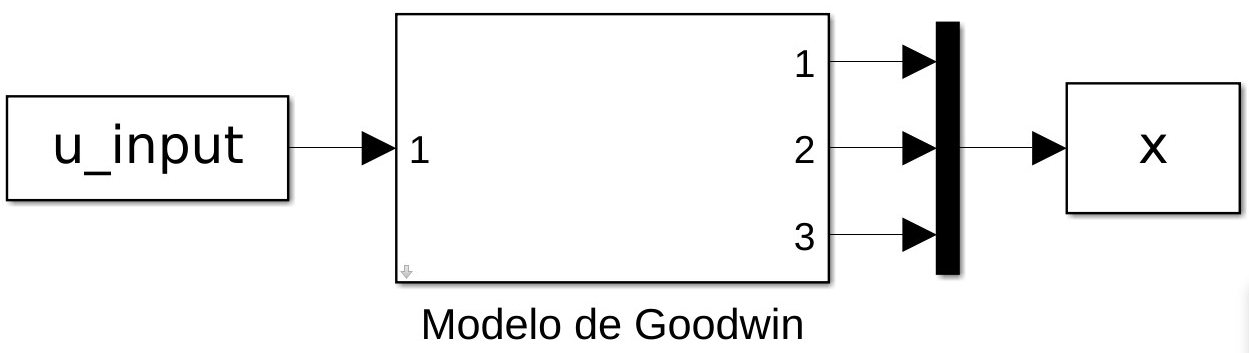

Subsistema Modelo de Goodwin:

### 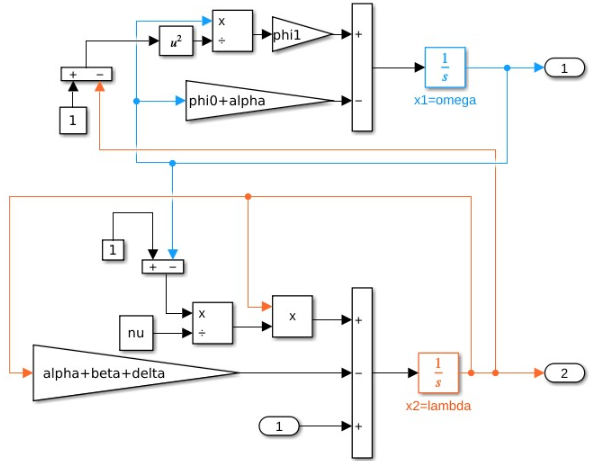

### **3.1. Curva de linealidad y punto de equilibrio**

#### **3.1.1. Curva de linealidad**

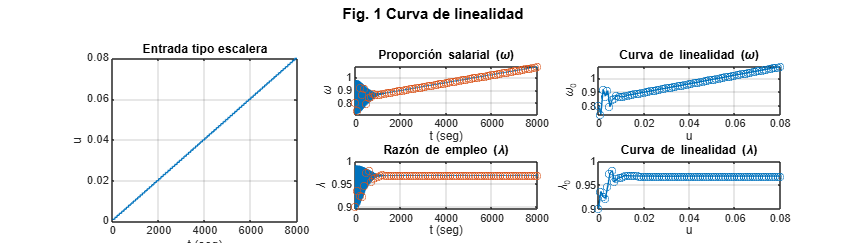

nu = 3;              % razón capital-producto
alpha = 0.025;       % tasa de crecimiento de la productividad
beta = 0.02;         % tasa de crecimiento de la población
delta = 0.01;        % tasa de depreciación
phi0 = 0.04/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0)=-0.04

x10 = 0.8; % Condiciones iniciales para omega
x20 = 0.9; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial

% Parámetros para la entrada escalón
u_esc = (0.001:0.001:0.08)';
Tw = 100;  % Duración de cada paso
Ts = 0.01; % Tiempo de muestreo

[t, u, Nh, Nw, tmax] = ladder(u_esc, Tw, Ts);

u_input = [t u];

% Ejecutar la simulación
sim('goodwin2')

fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2); % inversa de la curva de Phillips
omega_bar =  1-nu*(alpha+beta+delta);          % equilibrio proporción salarial
lambda_bar = fun_Phi_inv(alpha);               % equilibrio razón de empleo

u_0 = [0; u_esc];

% Extraer las señales de la simulación
omega = x.signals.values(:, 1); % Proporción salarial (omega)
lambda = x.signals.values(:, 2); % Razón de empleo (lambda)

% Valores de referencia para la curva de linealidad
omega_0 = omega(1:Nw:end, 1); % Valores de omega en cada escalón
lambda_0 = lambda(1:Nw:end, 1); % Valores de lambda en cada escalón

% Crear figura
figure('Units', 'normalized', 'Position', [0 0 1 0.5]);
sgtitle({'Fig. 1 Curva de linealidad'; ''}, 'FontSize', 12, 'FontWeight', 'bold');

% Entrada tipo escalera
subplot(2, 3, [1 4]);
plot(t, u);
xlabel('t (seg)');
ylabel('u');
title('Entrada tipo escalera');
grid on;

% Señal omega
subplot(2, 3, 2);
plot(x.time, omega);
hold on;
plot(x.time(1:Nw:end), omega(1:Nw:end), 'o');
xlabel('t (seg)');
ylabel('\omega');
title('Proporción salarial (\omega)');
grid on;

% Señal lambda
subplot(2, 3, 5);
plot(x.time, lambda);
hold on;
plot(x.time(1:Nw:end), lambda(1:Nw:end), 'o');
xlabel('t (seg)');
ylabel('\lambda');
title('Razón de empleo (\lambda)');
grid on;

% Curva de linealidad para omega
subplot(2, 3, 3);
plot(u_0, omega_0, 'o-');
xlabel('u');
ylabel('\omega_0');
title('Curva de linealidad (\omega)');
grid on;

% Curva de linealidad para lambda
subplot(2, 3, 6);
plot(u_0, lambda_0,'o-');
xlabel('u');
ylabel('\lambda_0');
title('Curva de linealidad (\lambda)');
grid on;

#### 3.1.2. Punto de equilibrio

% Punto de equilibrio simulación
Tabla = array2table([u_0 omega_0 lambda_0],'VariableNames',{'u_0','omega_0','lambda_0'});
disp(Tabla)

     u_0     omega_0    lambda_0
    _____    _______    ________

        0        0.8        0.9 
    0.001    0.73794    0.93668 
    0.002     0.9183    0.92569 
    0.003    0.86842     0.9219 
    0.004    0.90963    0.94615 
    0.005     0.7918    0.97412 
    0.006    0.84562    0.98026 
    0.007    0.85324    0.95636 
    0.008      0.875    0.96274 
    0.009    0.87003    0.96494 
     0.01    0.86398    0.96644 
    0.011    0.86414    0.96864 
    0.012    0.87072    0.96982 
    0.013    0.87705    0.96937 
    0.014    0.87965    0.96878 
    0.015    0.88192    0.96884 
    0.016    0.88535    0.96888 
    0.017    0.88852    0.96878 
    0.018    0.89154    0.96874 
    0.019    0.89467    0.96871 
     0.02    0.89774    0.96867 
    0.021    0.90082    0.96864 
    0.022    0.90388    0.96861 
    0.023    0.90694    0.96858 
    0.024    0.90999    0.96855 
    0.

% Punto de equilibrio análitico
syms omega lambda;
nu = 3;
alpha = 0.025;
beta = 0.02;
delta = 0.01;
phi0 = 0.04 / (1 - 0.04^2);
phi1 = 0.04^3 / (1 - 0.04^2);

fun_Phi = @(x) phi1./(1-x).^2- phi0;           % Phillips curve, equation (25)
fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2); % inverse of Phillips curve

u = 0.05;

% Define the ODE function in MATLAB
f1 = omega*(fun_Phi(lambda)-alpha) == 0;                 % d(omega)/dt
f2 = lambda*((1-omega)/nu-alpha-beta-delta) + u == 0;        % d(lambda)/dt

equations = [f1 f2];

sol = vpasolve(equations);
sol.omega

$$ans = \left(\begin{array}{c} 0.98986080837931183169640146709267\\ 0\\ 0.98043504960885384877697131397242 \end{array}\right)$$

sol.lambda

$$ans = \left(\begin{array}{c} 0.96861175897128277609096165758973\\ -0.17964071856287425149700598802395\\ 1.0313882410287172239090383424103 \end{array}\right)$$

punto_e = double([sol.omega(1) sol.lambda(1)])

punto_e =     0.9899    0.9686


sol = solve(equations);
punto_e = double([sol.omega(3) sol.lambda(3)])

punto_e =     0.9899    0.9686


Se toma el siguiente punto de equilibrio: u0 = 0.05, x0 = [0.9899, 0.9686].

#### 3.1.3. Linealización con `linmod `

nu = 3;              % razón capital-producto
alpha = 0.025;       % tasa de crecimiento de la productividad
beta = 0.02;         % tasa de crecimiento de la población
delta = 0.01;        % tasa de depreciación
phi0 = 0.04/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % parámetro de la curva de Phillips, Phi(0)=-0.04

x10 = 0.8; % Condiciones iniciales para omega
x20 = 0.9; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial

tmax = 100;
t = linspace(0, tmax, 1000)'; % Vector de tiempo con 1000 puntos entre 0 y tmax
x0 = [0.9899, 0.9686];        % Punto de equilibrio
u0 = 0.05;                    % Entrada

% Ejecutar la simulación
[A,B,C,D] = linmod('goodwin_linmod', x0, u0);

% Ecuación de estado
S = ss(A,B,C,D)


S =
 
  A = 
               x1          x2
   x1  -4.872e-05       4.099
   x2     -0.3229    -0.05163
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


Ecuación de estado


$$\begin{array}{l}
\dot{x} =\left\lbrack \begin{array}{cc}
-4\ldotp 872e-05 & 4\ldotp 099\\
-0\ldotp 3229 & -0\ldotp 05163
\end{array}\right\rbrack \cdot x+\left\lbrack \begin{array}{c}
0\\
1
\end{array}\right\rbrack \cdot u\\
y=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \cdot x+\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \cdot u
\end{array}$$


% Matriz de funciones de transferencia
syms s
result = C * inv(s*eye(2) - A) * B + D;
result

$$result = \left(\begin{array}{c} \frac{2215382893578590400000}{540431955284459520000\,s^{2}+27930634501072423216\,s+715274649808211273869}\\ \frac{30000\,\left(18014398509481984\,s+877706996161\right)}{540431955284459520000\,s^{2}+27930634501072423216\,s+715274649808211273869} \end{array}\right)$$

#### 3.1.4. Comparación en simulación del modelo lineal y el modelo no lineal

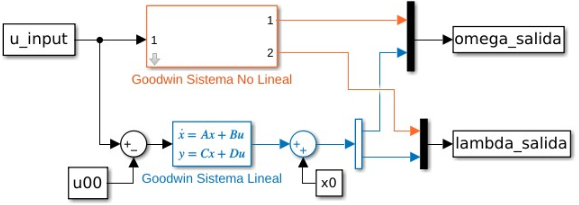

Valores de la entrada **cerca** del punto de operación para la entrada constante:

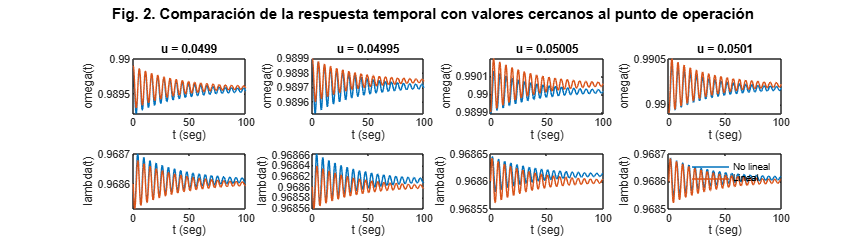

nu = 3;              % capital-to-output ratio
alpha = 0.025;       % productivity growth rate
beta = 0.02;         % population growth rate
delta = 0.01;        % depreciation rate

% Phillips curve parameters
phi0 = 0.04/(1-0.04^2); % Phillips curve parameter, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % Phillips curve parameter, Phi(0)=-0.04

% Create function handles for Phillips curve
fun_Phi = @(x) phi1./(1-x).^2 - phi0;           % Phillips curve, equation (25)
fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2);  % inverse of Phillips curve

% Initial conditions
x10 = 0.9899; % Condiciones iniciales para omega
x20 = 0.9686; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial
T = 100;             % time in years
tmax = 100;

x0 = [0.9899 0.9686];
u0 = 0.05;
[A,B,C,D] = linmod('goodwin_linmod',x0,u0);
u_vec = u0 + [-0.0001 -0.00005 0.00005 0.0001]; % Valor de las entradas alrededor del punto de equilibrio
N = length(u_vec);
figure('Units','normalized','Position',[0 0 1 0.5])
for i = 1:N
    u_input = [t u_vec(i)+0*t];
    u00 = [t u0+0*t];
    sim('goodwin_comparacion')
    subplot(2,N,i)
    t = omega_salida.time;
    omega_salida_NL = omega_salida.signals.values(:,1);
    omega_salida_L = omega_salida.signals.values(:,2);
    plot(t,omega_salida_NL,t,omega_salida_L), xlabel('t (seg)'), ylabel('omega(t)'), title(['u = ' num2str(u_vec(i))])
    subplot(2,N,i+N)
    t = lambda_salida.time;
    lambda_salida_NL = lambda_salida.signals.values(:,1);
    lambda_salida_L = lambda_salida.signals.values(:,2);
    plot(t,lambda_salida_NL,t,lambda_salida_L), xlabel('t (seg)'), ylabel('lambda(t)')
end
sgtitle({'Fig. 2. Comparación de la respuesta temporal con valores cercanos al punto de operación';''},'FontSize',12,'FontWeight','bold')
legend({'No lineal' 'Lineal'})
legend('boxoff')

Valores de la entrada **lejos** del punto de operación para la entrada constante:

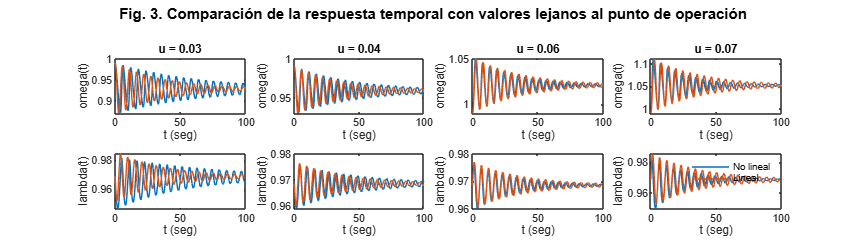

nu = 3;              % capital-to-output ratio
alpha = 0.025;       % productivity growth rate
beta = 0.02;         % population growth rate
delta = 0.01;        % depreciation rate

% Phillips curve parameters
phi0 = 0.04/(1-0.04^2); % Phillips curve parameter, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % Phillips curve parameter, Phi(0)=-0.04

% Create function handles for Phillips curve
fun_Phi = @(x) phi1./(1-x).^2 - phi0;           % Phillips curve, equation (25)
fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2);  % inverse of Phillips curve

% Initial conditions
x10 = 0.9899; % Condiciones iniciales para omega
x20 = 0.9686; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial
T = 100;             % time in years
tmax = 100;

x0 = [0.9899 0.9686];
u0 = 0.05;
[A,B,C,D] = linmod('goodwin_linmod',x0,u0);
u_vec = u0 + [-0.02 -0.01 0.01 0.02]; % Valor de las entradas alrededor del punto de equilibrio
N = length(u_vec);
figure('Units','normalized','Position',[0 0 1 0.5])
for i = 1:N
    u_input = [t u_vec(i)+0*t];
    u00 = [t u0+0*t];
    sim('goodwin_comparacion')
    subplot(2,N,i)
    t = omega_salida.time;
    omega_salida_NL = omega_salida.signals.values(:,1);
    omega_salida_L = omega_salida.signals.values(:,2);
    plot(t,omega_salida_NL,t,omega_salida_L), xlabel('t (seg)'), ylabel('omega(t)'), title(['u = ' num2str(u_vec(i))])
    subplot(2,N,i+N)
    t = lambda_salida.time;
    lambda_salida_NL = lambda_salida.signals.values(:,1);
    lambda_salida_L = lambda_salida.signals.values(:,2);
    plot(t,lambda_salida_NL,t,lambda_salida_L), xlabel('t (seg)'), ylabel('lambda(t)')
end
sgtitle({'Fig. 3. Comparación de la respuesta temporal con valores lejanos al punto de operación';''},'FontSize',12,'FontWeight','bold')
legend({'No lineal' 'Lineal'})
legend('boxoff')

Valores de la entrada **cerca** del punto de operación para la entrada sinusoidal:

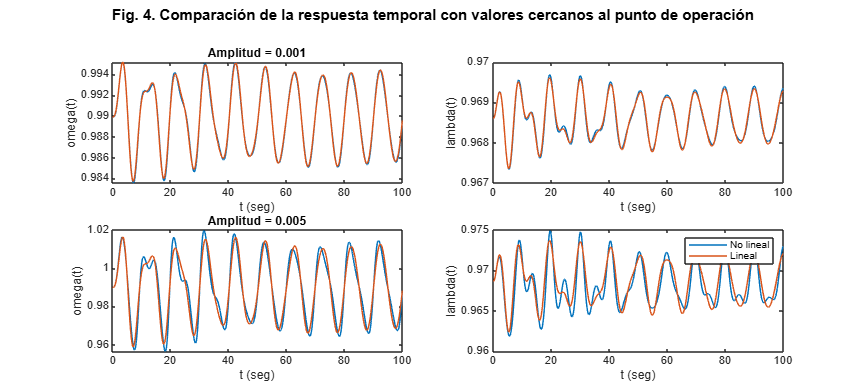

nu = 3;              % capital-to-output ratio
alpha = 0.025;       % productivity growth rate
beta = 0.02;         % population growth rate
delta = 0.01;        % depreciation rate

% Phillips curve parameters
phi0 = 0.04/(1-0.04^2); % Phillips curve parameter, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % Phillips curve parameter, Phi(0)=-0.04

% Create function handles for Phillips curve
fun_Phi = @(x) phi1./(1-x).^2 - phi0;           % Phillips curve, equation (25)
fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2);  % inverse of Phillips curve

% Initial conditions
x10 = 0.9899; % Condiciones iniciales para omega
x20 = 0.9686; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial
T = 100;             % time in years
tmax = 100;

x0 = [0.9899 0.9686];
u0 = 0.05;
[A,B,C,D] = linmod('goodwin_linmod',x0,u0);

% Generar entrada senoidal
frecuencia = 0.1; % Frecuencia del seno (Hz)
t = linspace(0, T, 1000)'; % Vector de tiempo (columna)
u0 = 0.05+0*t; % Entrada base constante

% Crear la señal como estructura para Simulink
clear u00;
u00.time = t; % Tiempo
u00.signals.values = u0; % Valores de la señal
u00.signals.dimensions = 1; % Dimensión de la señal

% Valores de amplitud a probar
amplitudes = [0.001, 0.005]; % Amplitudes diferentes

N = length(amplitudes); % Número de amplitudes
figure('Units','normalized','Position',[0 0 1 0.8])

for i = 1:N
    % Generar entrada senoidal con la amplitud actual
    amplitud = amplitudes(i);
    u0 = 0.05+0*t; % Entrada base constante
    u_seno = u0 + amplitud * sin(2 * pi * frecuencia * t); % Entrada senoidal centrada
    
    % Crear la señal como estructura para Simulink
    entrada_seno.time = t; % Tiempo
    entrada_seno.signals.values = u_seno; % Valores de la señal
    entrada_seno.signals.dimensions = 1; % Dimensión de la señal
    
    % Simulación
    u_input = entrada_seno;
    sim('goodwin_comparacion')

    % Graficar resultados
    subplot(N, 2, 2*i-1)
    t = omega_salida.time;
    omega_salida_NL = omega_salida.signals.values(:,1); % Salida no lineal
    omega_salida_L = omega_salida.signals.values(:,2);  % Salida lineal
    plot(t, omega_salida_NL, t, omega_salida_L)
    xlabel('t (seg)')
    ylabel('omega(t)')
    title(['Amplitud = ', num2str(amplitud)])
    
    subplot(N, 2, 2*i)
    t = lambda_salida.time;
    lambda_salida_NL = lambda_salida.signals.values(:,1);
    lambda_salida_L = lambda_salida.signals.values(:,2);
    plot(t, lambda_salida_NL, t, lambda_salida_L)
    xlabel('t (seg)')
    ylabel('lambda(t)')
end

sgtitle({'Fig. 4. Comparación de la respuesta temporal con valores cercanos al punto de operación';''}, 'FontSize', 12, 'FontWeight', 'bold')
legend({'No lineal', 'Lineal'})

Valores de la entrada **lejos** del punto de operación para la entrada sinusoidal:

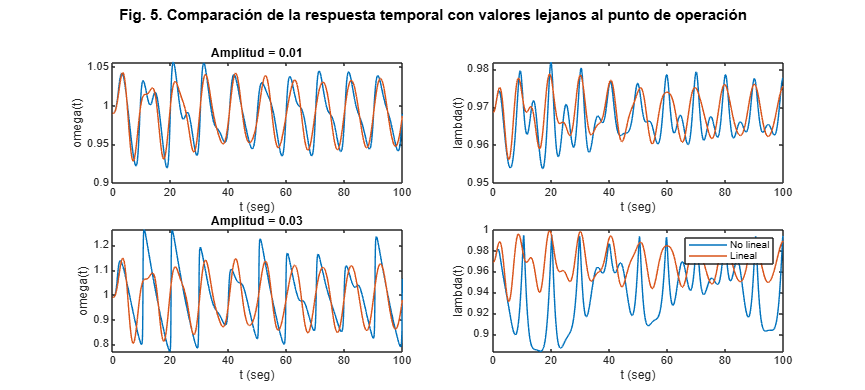

nu = 3;              % capital-to-output ratio
alpha = 0.025;       % productivity growth rate
beta = 0.02;         % population growth rate
delta = 0.01;        % depreciation rate

% Phillips curve parameters
phi0 = 0.04/(1-0.04^2); % Phillips curve parameter, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % Phillips curve parameter, Phi(0)=-0.04

% Create function handles for Phillips curve
fun_Phi = @(x) phi1./(1-x).^2 - phi0;           % Phillips curve, equation (25)
fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2);  % inverse of Phillips curve

% Initial conditions
x10 = 0.9899; % Condiciones iniciales para omega
x20 = 0.9686; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial
T = 100;             % time in years
tmax = 100;

x0 = [0.9899 0.9686];
u0 = 0.05;
[A,B,C,D] = linmod('goodwin_linmod',x0,u0);

% Generar entrada senoidal
frecuencia = 0.1; % Frecuencia del seno (Hz)
t = linspace(0, T, 1000)'; % Vector de tiempo (columna)
u0 = 0.05+0*t; % Entrada base constante

% Crear la señal como estructura para Simulink
clear u00;
u00.time = t; % Tiempo
u00.signals.values = u0; % Valores de la señal
u00.signals.dimensions = 1; % Dimensión de la señal

% Valores de amplitud a probar
amplitudes = [0.01, 0.03]; % Amplitudes diferentes

N = length(amplitudes); % Número de amplitudes
figure('Units','normalized','Position',[0 0 1 0.8])

for i = 1:N
    % Generar entrada senoidal con la amplitud actual
    amplitud = amplitudes(i);
    u0 = 0.05+0*t; % Entrada base constante
    u_seno = u0 + amplitud * sin(2 * pi * frecuencia * t); % Entrada senoidal centrada
    
    % Crear la señal como estructura para Simulink
    entrada_seno.time = t; % Tiempo
    entrada_seno.signals.values = u_seno; % Valores de la señal
    entrada_seno.signals.dimensions = 1; % Dimensión de la señal
    
    % Simulación
    u_input = entrada_seno;
    sim('goodwin_comparacion')

    % Graficar resultados
    subplot(N, 2, 2*i-1)
    t = omega_salida.time;
    omega_salida_NL = omega_salida.signals.values(:,1); % Salida no lineal
    omega_salida_L = omega_salida.signals.values(:,2);  % Salida lineal
    plot(t, omega_salida_NL, t, omega_salida_L)
    xlabel('t (seg)')
    ylabel('omega(t)')
    title(['Amplitud = ', num2str(amplitud)])
    
    subplot(N, 2, 2*i)
    t = lambda_salida.time;
    lambda_salida_NL = lambda_salida.signals.values(:,1);
    lambda_salida_L = lambda_salida.signals.values(:,2);
    plot(t, lambda_salida_NL, t, lambda_salida_L)
    xlabel('t (seg)')
    ylabel('lambda(t)')
end

sgtitle({'Fig. 5. Comparación de la respuesta temporal con valores lejanos al punto de operación';''}, 'FontSize', 12, 'FontWeight', 'bold')
legend({'No lineal', 'Lineal'})

### 3.2. Aplicación del *método de Routh-Hurwitz* al modelo lineal.

Veamos las soluciones del sistema: 

A = [-4.872e-05, 4.099; -0.3229, -0.05163];

syms s;

% Calcular el determinante de (s*I - A)
determinante = det(s*eye(2) - A);

disp('Polinomio característico:');

Polinomio característico:


disp(determinante);

$$s^{2}+\frac{23832603047422381982727\,s}{461168601842738790400000}+\frac{488310999185457124061981297}{368934881474191032320000000}$$

% Resolver la ecuación det(s*I - A) = 0
soluciones = solve(determinante, s);

% Mostrar las soluciones
disp('Las soluciones (autovalores) son:');

Las soluciones (autovalores) son:


disp(soluciones);

$$\left(\begin{array}{c} -\frac{23832603047422381982727}{922337203685477580800000}-\frac{\sqrt{1125400510825924104600108116933884078914289387471}\,\mathrm{i}}{922337203685477580800000}\\ -\frac{23832603047422381982727}{922337203685477580800000}+\frac{\sqrt{1125400510825924104600108116933884078914289387471}\,\mathrm{i}}{922337203685477580800000} \end{array}\right)$$

Ahora, le damos valores a todos los parámetros menos a ***beta*** para obtener el rango del parámetro que permite la estabilidad del sistema*:*

syms s beta;

% Parámetros
nu = 3;
alpha = 0.025;
%beta = 0.02;
delta = 0.01;
phi0 = 0.04 / (1 - 0.04^2);
phi1 = 0.04^3 / (1 - 0.04^2);

% Punto de equilibrio
lambda_star = 0.9686;
omega_star = 0.9899;

% Derivadas parciales
dPhi_dlambda = @(lambda) 2 * phi1 ./ (1 - lambda).^3;

% Matriz Jacobiana
J = [
    (phi1 ./ (1 - lambda_star)^2 - phi0 - alpha), omega_star * dPhi_dlambda(lambda_star);
    -lambda_star / nu, (1 - omega_star) / nu - alpha - beta - delta
];

% Calcular el determinante de (J - s*I)
determinante = det(J - s*eye(2));
determinante

$$determinante = \frac{877706996161\,\beta }{18014398509481984}+\frac{1070124712211452051\,s}{33776997205278720000}+\beta \,s+s^{2}+\frac{238424707728042236583}{180143985094819840000}$$

term1 = 877706996161 * beta / 18014398509481984;
term2 = 1070124712211452051 * s / 33776997205278720000;
term3 = beta * s;
term4 = s^2;
term5 = 238424707728042236583 / 180143985094819840000;

% Expresión completa
expr = term1 + term2 + term3 + term4 + term5;

% Reorganizar en la forma estándar
expr_standard = collect(expr, s)

$$expr\_standard = s^{2}+\left(\beta +\frac{2786783104717323}{87960930222080000}\right)\,s+\frac{877706996161\,\beta }{18014398509481984}+\frac{186269302912533}{140737488355328}$$

Simplificando fracciones:


$$S^2 +\left(0\ldotp 0316910722462181+\beta \right)\cdot s+\left(0\ldotp 0487163549928359\cdot \beta +1\ldotp 32363476210837\right)$$


Como es un polinomio de grado 2, necesitamos que los coeficientes sean positivos:


$$\left(0\ldotp 0316910722462181+\beta \right)>0$$



$$\left(0\ldotp 0487163549928359\cdot \beta +1\ldotp 32363476210837\right)>0$$


Es decir,


$$\beta >0\ldotp 0316910722462181$$



$$\beta >\frac{-1\ldotp 32363476210837}{0\ldotp 0487163549928359}=-27\ldotp 170233$$


Es decir,

$\beta \in \left(-0\ldotp 031691072246218,\infty \right)$ para conservar la estabilidad del sistema.

Vamos a darle valores a beta por dentro y fuera del intervalo de estabilidad para verificar que el resultado es correcto:

% Parámetros fijos
nu = 3;              % capital-to-output ratio
alpha = 0.025;       % productivity growth rate
delta = 0.01;        % depreciation rate

% Phillips curve parameters
phi0 = 0.04/(1-0.04^2); % Phillips curve parameter, Phi(0.96)=0
phi1 = 0.04^3/(1-0.04^2); % Phillips curve parameter, Phi(0)=-0.04

% Create function handles for Phillips curve
fun_Phi = @(x) phi1./(1-x).^2 - phi0;           % Phillips curve, equation (25)
fun_Phi_inv = @(x) 1 - (phi1/(x+phi0)).^(1/2);  % inverse of Phillips curve

% Inicialización
x10 = 0.9899; % Condiciones iniciales para omega
x20 = 0.9686; % Condiciones iniciales para lambda
y0 = 100;  % PIB inicial
T = 100;             % time in years
tmax = 300;
x0 = [x10 x20];
u0 = 0.05;

% Rango de valores de beta
beta_values = [-0.1, -0.05, 0.05, 0.1]; % Algunos valores dentro y fuera del rango de estabilidad

% Simulación para cada valor de beta
figure('Units', 'normalized', 'Position', [0 0 1 0.5])
for i = 1:length(beta_values)
    beta = beta_values(i); % Asignar valor de beta
    [A,B,C,D] = linmod('goodwin_linmod',x0,u0);
    u_input = [t 0*t];
    u00 = [t u0+0*t];
    sim('goodwin_comparacion'); % Simular el modelo
    
    % Extraer resultados para omega
    subplot(2, length(beta_values), i)
    t = omega_salida.time;
    omega_salida_L = omega_salida.signals.values(:, 2);
    plot(t, omega_salida_L), xlabel('t (seg)'), ylabel('\omega(t)')
    title(['\beta = ' num2str(beta)])
    
    % Extraer resultados para lambda
    subplot(2, length(beta_values), i + length(beta_values))
    t = lambda_salida.time;
    lambda_salida_L = lambda_salida.signals.values(:, 2);
    plot(t, lambda_salida_L), xlabel('t (seg)'), ylabel('\lambda(t)')
end

% Título general y leyenda
sgtitle({'Simulación con diferentes valores de \beta (Modelo lineal)'; ''}, 'FontSize', 12, 'FontWeight', 'bold')

Verificación con la función ***routh_hurwitz*****:**

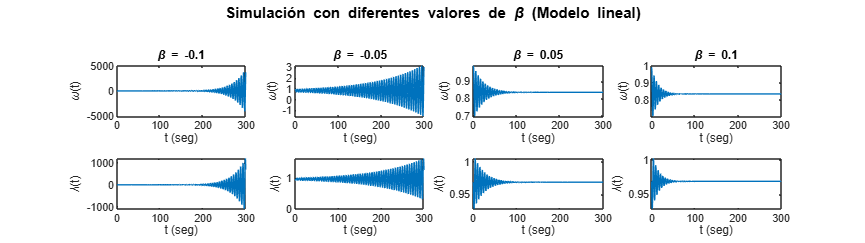

beta = [-0.1, -0.05, 0.05, 0.1];

for i = 1:4
    if i <= 2
        disp('Inestable:')
    else
        disp('Estable:')
    end
    [M, L] = routh_hurwitz([1 0.031691072246218+beta(i) 0.0487163549928359*beta(i)+1.32363476210837]);
    L
end

Inestable:


$$L = \left(\begin{array}{c} 1.0\\ -0.068308927753782000547033703696798\\ 1.3187631266090864556872475077398 \end{array}\right)$$

Inestable:


$$L = \left(\begin{array}{c} 1.0\\ -0.018308927753782004710370046041135\\ 1.3211989443587282000436289308709 \end{array}\right)$$

Estable:


$$L = \left(\begin{array}{c} 1.0\\ 0.08169107224621799390185117317742\\ 1.3260705798580116887563917771331 \end{array}\right)$$

Estable:


$$L = \left(\begin{array}{c} 1.0\\ 0.13169107224621801055519654255477\\ 1.3285063976076534331127732002642 \end{array}\right)$$

### 3.3. Análisis de sensibilidad e incertidumbre.

En el modelo trabajado, no es posible asignar más del 15% de incertidumbre a los parámetros del modelo debido a problemas de integración numérica. Al superar este límite, el solver genera errores relacionados con la imposibilidad de cumplir tolerancias sin reducir el paso a un valor mínimo, lo que interrumpe los cálculos y provoca fallos en las asignaciones de salida. Tras pruebas, se determinó que el modelo es estable únicamente con incertidumbres de hasta un 10% en todos los parámetros.

#### 3.3.1. Gráfico de incertidumbre 

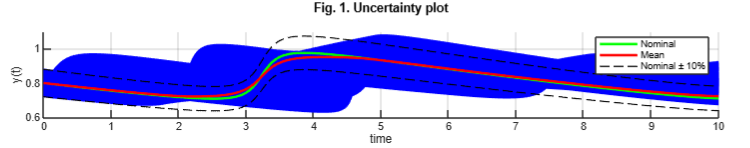

#### 3.3.2. Análisis de sensibilidad escalar 

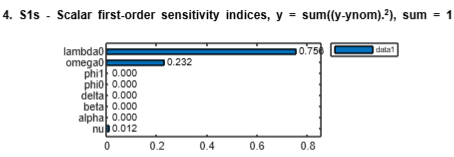

#### 3.3.3. Gráfico de muestras 

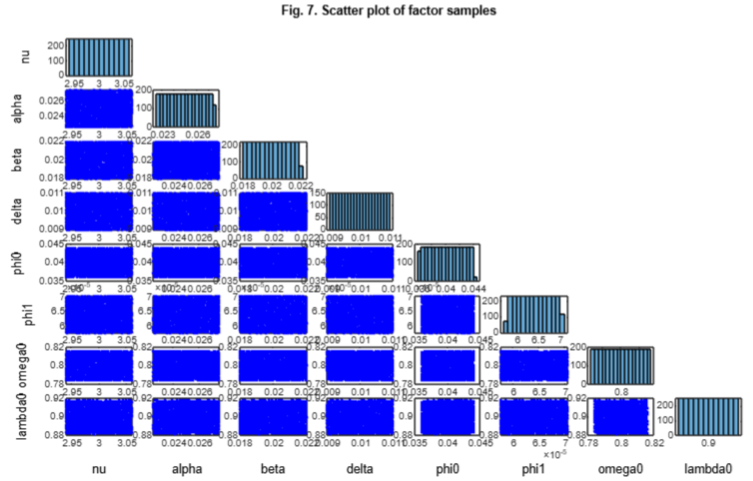

Veamos que pasa si reducimos la incertidumbre de los parámetros lambda0 y omega0 a 2%:

#### 3.3.4. Gráfico de incertidumbre 

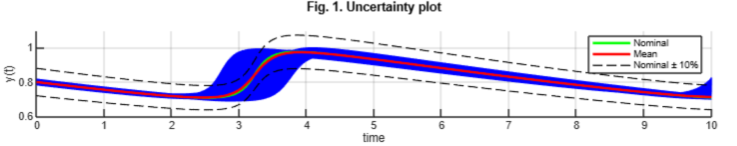

#### 3.3.5. Análisis de sensibilidad escalar 

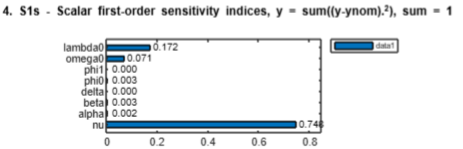

Ahora vamos a reducir la incertidumbre de nu a 2% y la de lambda0 y omega0 a 1%:

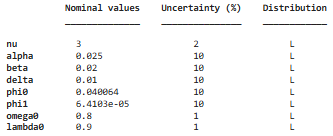

#### 3.3.6. Gráfico de incertidumbre 

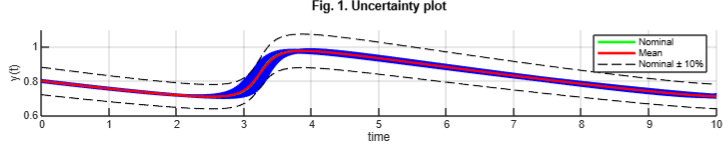

#### 3.3.7. Análisis de sensibilidad escalar 

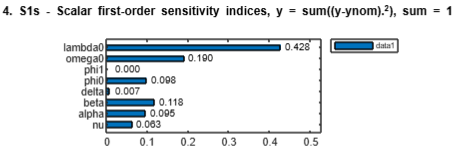

## 4. Discusión

El análisis realizado sobre el modelo de Goodwin ha permitido validar además de contrastar varias de las hipótesis iniciales y revelar importantes detalles sobre la dinámica entre el mercado laboral y la distribución del ingreso en una economía.

### 4.1. Validación de Hipótesis sobre Puntos de Equilibrio

La primera hipótesis sobre la existencia de puntos de equilibrio se confirmó tanto analítica como numéricamente. Este resultado tiene una interpretación económica: representa un estado estacionario donde la participación de los salarios en el ingreso nacional y la tasa de empleo se mantienen constantes. 

La linealización en torno al punto de equilibrio demostró ser efectiva para pequeñas perturbaciones, validando nuestra segunda hipótesis. Económicamente, esto sugiere que para pequeñas fluctuaciones en el mercado laboral o en la distribución del ingreso, podemos utilizar aproximaciones lineales para predecir el comportamiento del sistema. No obstante, ante grandes shocks económicos (como crisis financieras o cambios estructurales), el modelo lineal pierde precisión, necesitándose el modelo no lineal completo.

### 4.2. Dinámica del Sistema y Estabilidad

El análisis de Routh-Hurwitz confirmó nuestra hipótesis sobre la existencia de rangos específicos de estabilidad, particularmente en relación con la tasa de crecimiento poblacional ($\beta$). Este hallazgo tiene las siguientes implicaciones económicas:

La existencia de un rango específico de $\beta$ para la estabilidad del sistema sugiere que el crecimiento poblacional no puede ser demasiado bajo para mantener un equilibrio económico sostenible. Este resultado tiene una interpretación económica intuitiva: 

- Un $\beta$ demasiado bajo puede resultar en escasez de mano de obra, presionando los salarios al alza de manera insostenible y potencialmente erosionando la participación de las ganancias en el ingreso nacional.

### 4.3. Sensibilidad e Incertidumbre

El análisis de sensibilidad e incertidumbre reveló patrones significativos que proporcionan detalles importantes sobre la dinámica del modelo de Goodwin:

La respuesta temporal del sistema mostró una sensibilidad particularmente alta a ciertos parámetros. Para mantener las desviaciones de la respuesta dentro de un margen del 10% respecto al valor nominal, fue necesario limitar significativamente la variación de los parámetros más sensibles. Específicamente, la variación en la tasa de capital a salida ($\nu$) tuvo que reducirse al 2%, mientras que las condiciones iniciales de $\omega$ y $\lambda$ debieron limitarse al 1%.

**Condiciones iniciales de **$\omega$ y $\lambda$: La notable sensibilidad a las condiciones iniciales revela una característica fundamental del modelo de Goodwin: la importancia de la historia pasada en la trayectoria económica. Esto sugiere que: 

- Los niveles iniciales de empleo y participación salarial condicionan fuertemente la evolución posterior del sistema

- Las intervenciones políticas deben considerar cuidadosamente el estado actual de la economía

- La recuperación tras una crisis puede seguir patrones muy diferentes dependiendo de las condiciones en que se inicie

**Tasa de capital a salida (**$\nu$**)**: Emergió como uno de los parámetros más sensibles del modelo, lo cual tiene sentido económico profundo. Esta alta sensibilidad indica que la relación entre el capital y la producción es fundamental para la dinámica cíclica del sistema. Pequeñas variaciones pueden generar cambios significativos en la amplitud de los ciclos económico, la velocidad de ajuste entre salarios y empleo, y la distribución del ingreso entre trabajo y capital.

**Otros parámetros**: Contrario a lo que se esperaba inicialmente, la tasa de crecimiento de la productividad ($\alpha$) mostró una sensibilidad menor, sugiriendo que el sistema es más robusto a cambios en la eficiencia productiva que a cambios en la relación capital-producto o en las condiciones iniciales. La relativa mayor robustez frente a cambios en otros parámetros indica que las políticas económicas podrían permitir mayor flexibilidad en estas variables sin comprometer significativamente la estabilidad del sistema.

### 4.4. Implicaciones para la Política Económica

El modelo de Goodwin revela una característica fundamental de las economías: los ciclos económicos pueden surgir naturalmente de la interacción entre salarios, empleo y capital, sin necesidad de perturbaciones externas. Esta dinámica se manifiesta a través de un mecanismo cíclico donde el aumento en el empleo fortalece el poder de negociación de los trabajadores, elevando los salarios. Sin embargo, salarios más altos reducen las ganancias y la inversión, lo que eventualmente disminuye el empleo, comenzando un nuevo ciclo.

La sensibilidad particular del modelo a la tasa de capital a salida ($\nu$) nos muestra cómo la eficiencia en el uso del capital productivo es crucial para la estabilidad económica. Este resultado sugiere que las políticas económicas deberían prestar especial atención a la calidad de la inversión y a la eficiencia del capital, más que concentrarse exclusivamente en su cantidad.

### 4.5. Limitaciones y Extensiones del Análisis

La principal limitación del modelo radica en su simplificación de la realidad económica moderna. Si bien captura efectivamente la dinámica fundamental entre trabajo y capital, no considera elementos importantes como el sector financiero o el comercio internacional. Esta simplificación, aunque útil para entender los mecanismos básicos de los ciclos económicos, sugiere que las predicciones del modelo deben interpretarse como tendencias de largo plazo más que como herramientas de pronóstico preciso.

El modelo resulta valioso para comprender por qué las economías capitalistas tienden a experimentar ciclos recurrentes en la distribución del ingreso y el empleo, incluso en ausencia de shocks externos. Esta comprensión es fundamental para el diseño de políticas económicas que busquen moderar, más que eliminar completamente, las fluctuaciones económicas del sistema.

Futuras investigaciones podrían enfocarse en incorporar estos elementos para obtener un modelo más completo de los ciclos económicos modernos.

## 5. Referencias

[1] Carlos M. Velez S. (2024). *Sistemas dinámicos en contexto: Modelación matemática, simulación, estimación y control con MATLAB*.

[2] Carlos M. Velez S. (2024). Global sensitivity and uncertainty analysis (GSUA) (https://www.mathworks.com/matlabcentral/fileexchange/47758-global-sensitivity-and-uncertainty-analysis-gsua), MATLAB Central File Exchange. Recuperado 23 noviembre, 2024.

[3] Grasselli, M.R., Costa Lima, B. An analysis of the Keen model for credit expansion, asset price bubbles and financial fragility. *Math Finan Econ* **6**, 191–210 (2012). https://doi.org/10.1007/s11579-012-0071-8

[4] Grasselli, M. R. *The Goodwin Model*. McMaster University. [https://ms.mcmaster.ca/~grasselli/goodwin.html](https://ms.mcmaster.ca/~grasselli/goodwin.html)

[5] Almeida, Mafalda Oliveira Martins Bastos de (2017). "The Lotka-Volterra equations in finance and economics". Dissertação de Mestrado, Universidade de Lisboa. Instituto Superior de Economia e Gestão.

[6] Mahmud, Sri & Resmawan, Resmawan & Ismail, Sumarno & Nurwan, Nurwan & Taki, Febriani. (2022). Goodwin Model with Clustering Workers' Skills in Indonesian Economic Cycle. CAUCHY. 7. 249-266. 10.18860/ca.v7i2.13458. 

[7] Wikipedia contributors. (2023) *Goodwin model (economics)*. Wikipedia. [https://en.wikipedia.org/wiki/Goodwin_model_(economics)](https://en.wikipedia.org/wiki/Goodwin_model_(economics))

[8] MathWorks. *Simulink*. [https://la.mathworks.com/help/simulink/](https://la.mathworks.com/help/simulink/)